# Monthly and Quarterly Electricity Data

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

price = readmatrix("./data/electricity.xlsx", Sheet="price");
usage = readmatrix("./data/electricity.xlsx", Sheet="usage");
yr = readmatrix("./data/electricity.xlsx", Sheet="yr");
mth = readmatrix("./data/electricity.xlsx", Sheet="mth");

revenue = price.*usage;

## Task 1

The variable `usage` contains electricity usage data for each month from 1990 to 2019.

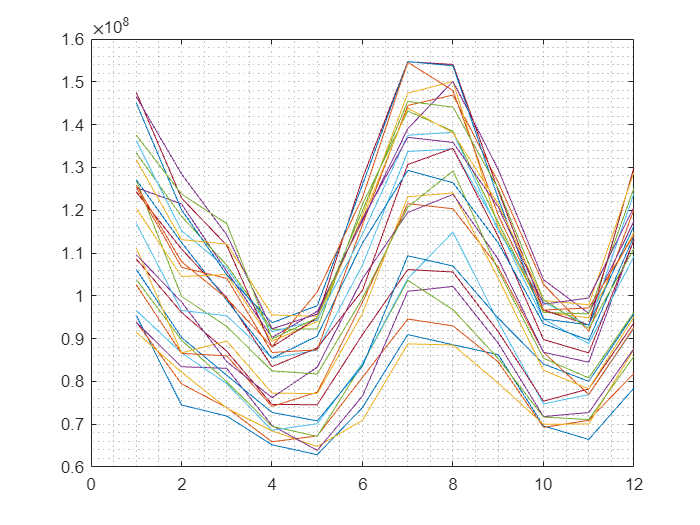

plot(mth, usage)
grid minor

## Task 2

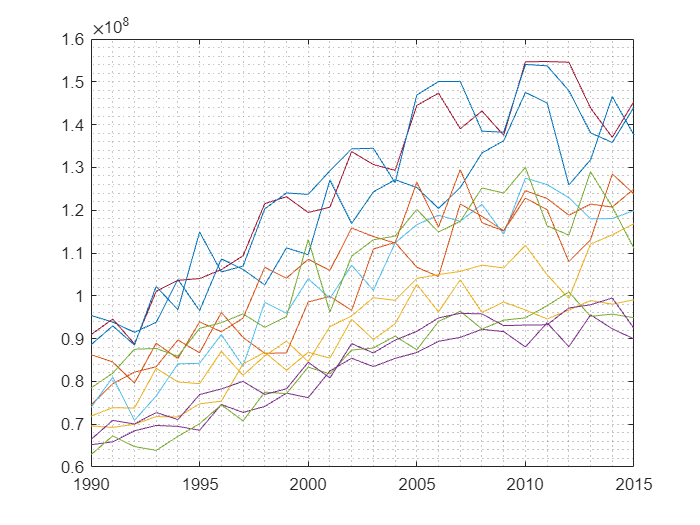

plot(yr, usage)
grid minor

## Task 3

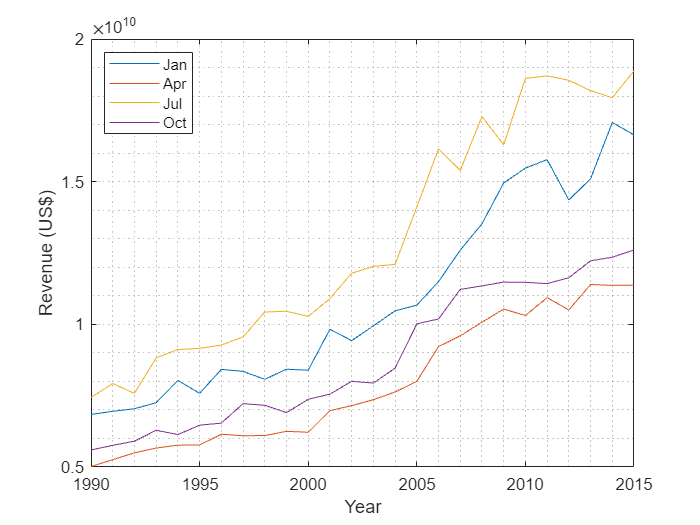

firstMonth = revenue(1:3:12, :);
plot(yr, firstMonth)
grid minor
legend(["Jan", "Apr", "Jul", "Oct"], "Location", "northwest")
xlabel("Year")
ylabel("Revenue (US$)")